localUsername = getenv('USERNAME');
listOfUsernames = {'aryan', 'Aryan Ritwajeet Jha'};
if ismember(localUsername,  listOfUsernames)
    % For user 'aryan', change the current directory to the specified path
    validationFolder = strcat("C:", filesep, "Users", filesep, localUsername, filesep, "Documents", filesep, ...
        "documents_general", filesep, "MultiPeriod-DistOPF-Benchmark", filesep, "functions", filesep, ...
        "OneTimeScripts", filesep, "validationAgainstOpenDSS_MATLAB");
    cd(validationFolder)
    addpath(genpath('dss_matlab\'))
    addpath(genpath('..\..\'))
    latex_interpreter
else
    fprintf("Are you not me? Might want to add the folder to the path or add folder to the workspace.\n");
end

systemName = sysInfo.systemName;
T = simInfo.T;
kVA_B = sysInfo.kVA_B;
kV_B = sysInfo.kV_B;
CVR = [0 0];

DSSObj = DSS_MATLAB.IDSS;

DSSText=DSSObj.Text;
DSSCircuit=DSSObj.ActiveCircuit;
DSSBus = DSSCircuit.ActiveBus;
% Locating the master file for this system, with some starting 
% information to get the simulation running
% DSSText.Command = strcat('Set DataPath = "C:\Users\', ...
%     localUsername, ['\Documents\documents_general\MultiPeriod-DistOPF-Benchmark\' ...
%     'functions\OneTimeScripts\validationAgainstOpenDSS_MATLAB\"']);
strSetPath = strcat('Set DataPath = "', char(validationFolder), '"');
DSSText.Command = strSetPath;

MasterFileString = strcat('Compile (.\', systemName, 'master_r.dss)'); 
DSSText.Command = MasterFileString;
text_powerdata_r = 'powerdata.txt';
Power_data = readmatrix(text_powerdata_r);
varNames0 = {"busNum", "P_L", "Q_L", "Q_C", "P_D", "busType"};
varNames = cellfun(@char, varNames0, 'UniformOutput', false);
busData = readtable(text_powerdata_r);
busData.Properties.VariableNames = varNames;

N = length(busData.busNum);
busNums = busData.busNum;
P_L = busData.P_L;
Q_L = busData.Q_L;
Q_C = busData.Q_C;
% P_D = busData.P_D;
busTypes = busData.busType;

## Load dss generation

loadShape = vald.loadShape;
strLoadShape = strcat('New Loadshape.LoadShape npts = ', num2str(T), ' interval = 1 mult = [', num2str(loadShape), ']');
DSSText.Command = strLoadShape;

stLoadTitle = '! Specifying Loads as Model 1 and 2 type loads. For no CVR, Model 2 loads will be blank';
DSSTest.Command = stLoadTitle;

for i = 1:N
    if P_L(i) || Q_L(i)
        % Model=1 is constant power load, Model=2 is constant current load
        sta1 = strcat('New load.S', num2str(busNums(i)),'P    Bus=',num2str(busNums(i)),...
            '.1   Phases=1   Model=1   kv=2.4018   kw=',num2str(P_L(i)*(1-(CVR(1)/2))),...
            '  kvar=',num2str(Q_L(i)*(1-(CVR(2)/2))),'   Vminpu=0.95  Vmaxpu=1.05 Daily = LoadShape');
        
       DSSText.Command = sta1;

       if CVR ~= [0 0]
           sta2 = strcat('New load.S', num2str(busNums(i)),'Z    Bus=',num2str(busNums(i)),...
               '.1   Phases=1  Model=2   kv=2.4018   kw=',num2str(P_L(i)*((CVR(1))/2)),...
               '  kvar=',num2str(Q_L(i)*((CVR(2))/2)),'    Vminpu=0.95  Vmaxpu=1.05 Daily = LoadShape');
              DSSText.Command = sta2;
       end
    end
end

## Line parameter

text_linedata_r = 'linedata.txt';
Line_data = readmatrix(text_linedata_r);

nBranch = size(Line_data,1);
for i = 1:nBranch
    stLn = strcat('New Line.L', num2str(i),'   Phases = 1  Bus1= ', num2str(Line_data(i,1)),'  bus2 = ',...
        num2str(Line_data(i,2)),'  r1=', num2str(Line_data(i,3)),...
        '  x1= ',num2str(Line_data(i,4)));
    DSSText.Command =stLn;
end

## PV Data

% qD= zeros(nBus,1);   % All the Q values in all the buses
% qD= Dec_Var*1000;   % DOPF
simName = vald.simInfo.simName;
V_copf = vald.V_copf;
busesWithDERs = vald.busesWithDERs_Area;
Pmpp_AreaFull_kW = kVA_B*vald.Pmpp_AreaFull;
kVA_AreaFull_kVA = kVA_B*vald.Sder_AreaFull;
% pD_AreaFull_1toT = vald.pD_AreaFull_1toT;

% pD_AreaFull_1toT_kW = pD_AreaFull_1toT*kVA_B;
loadShapePV = vald.loadShapePV;
% conn=wye
% PV_bus = [];%[68 98] ;


strLoadShapePV = strcat('New Loadshape.LoadShapePV npts = ', num2str(T), ' interval = 1 mult = [', num2str(loadShapePV), ']')

strLoadShapePV = 'New Loadshape.LoadShapePV npts =2 interval = 1 mult = [1  1]'


DSSText.Command = strLoadShapePV;

% for i = 1:N
for bus1 = busesWithDERs'
    Pmpp_j_kW = Pmpp_AreaFull_kW(bus1);
    kVA_j_kVA = kVA_AreaFull_kVA(bus1);
    % pDj_1toT_kW = pD_kW(bus1, 1:T);
    % if pD(i)
        % if isempty(find(PV_bus==i, 1))
            % stGa = strcat('New generator.', num2str(busNums(i)),'  Phases=1   Bus1=',num2str(busNums(i)),...
            %     '.1   kV = 2.4018 Model=1  kW=', num2str(pD(i)),'  kVAr=', num2str(qD(i)));
            % DSSText.Command = stGa;

            stGa = strcat('New PVSystem.PV', num2str(bus1),'  Phases=1   Bus1=', num2str(bus1),...
                '.1   kV = ', num2str(kV_B), ' kVA = ', num2str(kVA_j_kVA),  ...
                ' Daily = LoadShapePV ', ' Pmpp = ', num2str(Pmpp_j_kW), ...
                ' %cutin = 0.1 %cutout = 0.1');

            DSSText.Command = stGa;
            
        % else % generators for PV buses
        %     stGa = strcat('New generator.',num2str(busNums(i)),'  Phases=1   Bus1=',num2str(busNums(i)),...
        %         '.1   kV = 2.4018 Model=3 kW=',num2str(pD(i)),'  Minkvar = ',num2str(-3*abs(qD(i))));
        %     DSSText.Command = stGa;
        % end
        
    % end
end

## Storage

busesWithBatts_Area = vald.busesWithBatt_Area;
B0_Area_kWh = kVA_B*vald.B0_Area;
B_Area_1toT = kVA_B*vald.B_Area_1toT;
S_battMax_Area_kVA = kVA_B*vald.S_battMax_Area;
P_battMax_Area_kW = kVA_B*vald.P_battMax_Area;
nBatt_Area = vald.nBatt_Area;
chargeToPowerRatio = simInfo.chargeToPowerRatio;
V_min = simInfo.V_min;
V_max = simInfo.V_max;
etta_C = simInfo.etta_C;
etta_D = simInfo.etta_D;
soc_min = simInfo.soc_min;
soc_max = simInfo.soc_max;

for battBusNum = 1:nBatt_Area
    bus1 = busesWithBatts_Area(battBusNum);
    kVArated = S_battMax_Area_kVA(battBusNum);
    kWrated = P_battMax_Area_kW(battBusNum);
    kWhrated = chargeToPowerRatio*kWrated;
    percentStored = 100*(soc_min + soc_max)/2;
    percentReserve = soc_min*100;
    percentEffCharge = etta_C*100;
    percentEffDischarge = etta_D*100;
    Vminpu = V_min;
    Vmaxpu = V_max;

    strStorage = strcat('New Storage.Battery', num2str(bus1), ' phases = 1 bus1 = ', num2str(bus1), ...
        ' kV = ', num2str(kV_B), ' kVA = ', num2str(kVArated), ' kWrated = ', num2str(kWrated), ...
        ' kWhrated = ', num2str(kWhrated), ...
        ' %stored = ', num2str(percentStored), ' %reserve = ', num2str(percentReserve), ' %EffCharge = ', ...
        num2str(percentEffCharge), ' %EffDischarge = ', num2str(percentEffDischarge), ' %idlingkW = 0', ...
        ' Vminpu = ', num2str(Vminpu), ' Vmaxpu = ', num2str(Vmaxpu), ' DispMode = Follow');

    DSSText.Command = strStorage;
    % New Storage.Battery9 phases=1 bus1=9 kv=2.4018 kWrated=16 kWhrated=64 %stored=62.5 %reserve=30 %EffCharge = 95 %EffDischarge = 95 %idlingkW=0 vminpu=0.95 vmaxpu=1.05 DispMode=Follow
        % New Monitor.Battery9_states element=Storage.Battery9 mode=3 
    strMonStorage = strcat('New Monitor.Battery', num2str(bus1), '_states', ' element = Storage.Battery', num2str(bus1), ' mode=3');
    DSSText.Command = strMonStorage;

end


## Storage Controller

Pd_Area_1toT_kW = kVA_B*vald.Pd_Area_1toT;
Pc_Area_1toT_kW = kVA_B*vald.Pc_Area_1toT;
Pdc_Area_1toT_kW = Pd_Area_1toT_kW - Pc_Area_1toT_kW;

for battBusNum = 1:nBatt_Area
    bus1 = busesWithBatts_Area(battBusNum);
    dispatch = Pdc_Area_1toT_kW(battBusNum) / P_battMax_Area_kW(battBusNum);

    strLoadShapeSC = strcat('New LoadShape.SCLoadShape', num2str(bus1), ' interval = 1 npts = ', num2str(T), ' mult = [', num2str(dispatch), ']');

    DSSText.Command = strLoadShapeSC;

    % strSC = strcat('New StorageController.SC', num2str(bus1), ' Element = Line.l', num2str(bus1), ' terminal = 1', ' ElementList = [Battery', num2str(bus1), ']', ' modedis = loadshape', ' daily = SCLoadShape', num2str(bus1), ' eventlog = yes');
    strSC = strcat('New StorageController.SC', num2str(bus1), ' Element = Line.L1', ' terminal = 1', ' ElementList = [Battery', num2str(bus1), ']', ' modedis = loadshape', ' daily = SCLoadShape', num2str(bus1), ' eventlog = yes');

    DSSText.Command = strSC;

end

## Capacitors

smallkW = 0.000001;
% smallkW = 0
for i = 1:N
    if Q_C(i)
        stC = strcat('New generator.',num2str(busNums(i)),'C','  Phases=1   Bus1=',num2str(busNums(i)),...
            '   kV = 2.4018 Model=1 kW=',num2str(smallkW),'   kVAr = ',num2str(Q_C(i)));
        % stC = strcat('New Capacitor.C',num2str(busNums(i)),'  Phases=1   Bus1=',num2str(busNums(i)),...
        %     '   kV = 2.4018 kVAr=',num2str(Q_C(i)));
        DSSText.Command = stC;
    end
end

## Set Simulation Parameters

DSSText.Command = 'Set VoltageBases = [4.16]' ; %  ! ARRAY OF VOLTAGES IN KV
DSSText.Command = 'Set mode=Daily ';
DSSText.Command = 'Set stepsize=1h'; 

## Set, Solve, Save, Repeat

qB_Area_1toT_kVAr = kVA_B*vald.qB_Area_1toT;
% qD_AreaFull_1toT = vald.qD_AreaFull_1toT;
qD_AreaFull_1toT_kVAr = kVA_B*vald.qD_AreaFull_1toT;

for t = 1:T
    qB_Area_t = qB_Area_1toT_kVAr(:, t);
    for battBusNum = 1:nBatt_Area
        bus1 = busesWithBatts_Area(battBusNum);
    
        strStorageQ = strcat( 'Edit Storage.Battery', num2str(bus1), ' kVAr = ', num2str( qB_Area_t(battBusNum) ) );
    
        DSSText.Command = strStorageQ;
        % New Storage.Battery9 phases=1 bus1=9 kv=2.4018 kWrated=16 kWhrated=64 %stored=62.5 %reserve=30 %EffCharge = 95 %EffDischarge = 95 %idlingkW=0 vminpu=0.95 vmaxpu=1.05 DispMode=Follow
            % New Monitor.Battery9_states element=Storage.Battery9 mode=3 
        % strMonStorage = strcat('New Monitor.Battery', num2str(bus1), '_states', ' element = Storage.Battery', num2str(bus1), ' mode=3');
        % DSSText.Command = strMonStorage;

    end

    qD_AreaFull_t_kVAr = qD_AreaFull_1toT_kVAr(:, t);
    for bus1 = busesWithDERs'
        qDj_t_kVAr = qD_AreaFull_t_kVAr(bus1);
        strPVQ = strcat( 'Edit PVSystem.PV', num2str(bus1), ' kVAr = ', num2str( qDj_t_kVAr) );
    
        DSSText.Command = strPVQ;
    end

    DSSText.Command = 'CalcVoltageBases' ; %! PERFORMS ZERO LOAD POWER FLOW TO ESTIMATE VOLTAGE BASES

    DSSText.Command = strcat('Set number = ', num2str(t), ' hour = 0');
    
    DSSSolution     = DSSCircuit.Solution;
    
    DSSObj.AllowForms = false;

    DSSSolution.Solve;
    
    PVSystems = DSSCircuit.PVSystems;
    Storages = DSSCircuit.Storages;
    % Controllers = DSSCircuit.
    % Initialize variables to sum the generation values
    genNumber = PVSystems.First();
    genkWsum = 0.0;
    genkvarsum = 0.0;
    
    % Iterate through each generator
    while genNumber > 0
        genkWsum = genkWsum + PVSystems.kW();
        genkvarsum = genkvarsum + PVSystems.kvar();
        genNumber = PVSystems.Next();
    end
    
    % Now genkWsum and genkvarsum hold the total kW and kVAr generation, respectively
    
    Loads = DSSCircuit.Loads;
    loadnumber = Loads.First();
    loadkWsum = 0.0;
    loadkvarsum = 0.0;
    
    while loadnumber > 0
        loadkWsum = loadkWsum + Loads.kW();
        loadkvarsum = loadkvarsum + Loads.kvar();
        loadnumber = Loads.Next();
    end
    

    % loadkWsum, loadkvarsum

###     Save .DSS file

    ext = ".dss";
    % DSSText.Command = 'Set DataPath = "./generatedFiles/"'
    filename = char(strcat(systemName, "_", simName, "_T_", string(T), "_t_", string(t), ext))

filename = 'ieee123_MPCOPF_T_2_t_1.dss'

filename = 'ieee123_MPCOPF_T_2_t_2.dss'

    % filename = 'hello123.dss';
    saveCommand = ['Save Circuit "', filename, '"'];
    DSSText.Command = saveCommand;
    disp(strcat("DSS file exported to ", filename));

DSS file exported to ieee123_MPCOPF_T_2_t_1.dss


DSS file exported to ieee123_MPCOPF_T_2_t_2.dss


###     Extract Voltages

    % V_PU = [];
    V_PU = DSSCircuit.AllBusVmagPU;
    MytotalCircuitLosses= (DSSCircuit.Losses)/1000;
    
    DSSCircuit.SetActiveElement('Line.L1');
    MyPowerArray = DSSCircuit.ActiveCktElement.Powers;
    P_Sub = sum(MyPowerArray(1));
    Q_Sub = sum(MyPowerArray(2));
    Line_loss = MytotalCircuitLosses;
    V_opds = zeros(N,1);
    BUS_phase = DSSCircuit.AllNodeNames;
    for i = 1:length(BUS_phase)
        X = BUS_phase{i};
        X_len = length(X);
        col = str2double(X(end));
        row = str2double(X(1:(X_len-2)));
        V_opds(row,col) = V_PU(i);
    end
    V_opds = V_opds';
    
    disp('------------------------------------------------------------')

------------------------------------------------------------


------------------------------------------------------------


    
    disp(['Line Loss: ', num2str(Line_loss(1)),' kW'])

Line Loss: 10.6422 kW


Line Loss: 17.731 kW


    % else
    disp(['Substation Power: ', num2str(P_Sub),' kW + ', num2str(Q_Sub),' kVAr'])

Substation Power: 731.56 kW + 82.6226 kVAr


Substation Power: 956.9796 kW + 96.898 kVAr


    disp(['Total Load: ', num2str(loadkWsum), ' kW + ', num2str(loadkvarsum), ' kVAr'])

Total Load: 1163.197 kW + 640.012 kVAr


Total Load: 1163.197 kW + 640.012 kVAr


    disp(['Total Generation: ', num2str(genkWsum), ' kW + ', num2str(genkvarsum), ' kVAr' ])

Total Generation: 223.9731 kW + 76.5996 kVAr


Total Generation: 223.9731 kW + 76.5996 kVAr


    % disp(['Total Real Load: ', num2str(loadkWsum), ' kW'])
    % disp(['Total Reactive Load: ', num2str(loadkvarsum), ' kVAr'])
    disp(['Total PV Real Power Generation: ', num2str(genkWsum), ' kW'])

Total PV Real Power Generation: 223.9731 kW


Total PV Real Power Generation: 223.9731 kW


    disp(['Total Reactive Power Generation: ', num2str(genkvarsum), ' kVAr'])

Total Reactive Power Generation: 76.5996 kVAr


Total Reactive Power Generation: 76.5996 kVAr


###     Validate Simulation Against OpenDSS via System-wide Voltage Snapshot

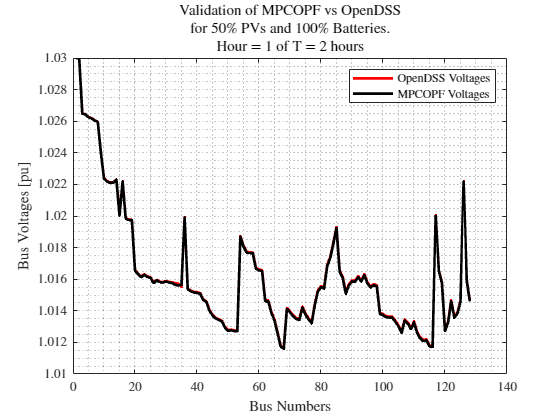

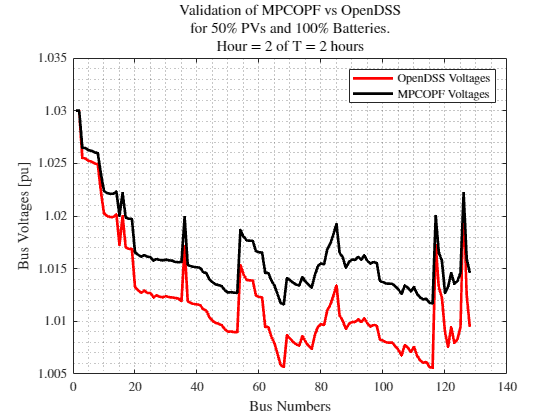

    DER_percent = vald.simInfo.DER_percent;
    Batt_percent = vald.simInfo.Batt_percent;
    figure
    % hold on;
    linewidth = 2.0;
    plot(V_opds, 'LineWidth', linewidth, 'Color', 'r');
    hold on;
    plot(V_copf, 'LineWidth', linewidth, 'Color', 'k')
    legend({"OpenDSS Voltages", strcat(simName, " Voltages")});
    title([strcat("Validation of ", simName, " vs OpenDSS"), strcat("for ", string(DER_percent), "\% PVs and ", string(Batt_percent), "\% Batteries."), ...
        strcat("Hour = ", string(t), " of T = ", string(T), " hours")]);
    ylabel("Bus Voltages [pu]")
    xlabel("Bus Numbers");
    grid minor;
    hold off;
    
    ext = ".png";
    figureFolder = "figures";
    isfolder(figureFolder) || mkdir(figureFolder); %#ok
    filename = strcat("MPOPF_vs_OpenDSS_T_", string(T), "_t_", string(t), "_pv_", string(DER_percent), "_batt_", string(Batt_percent), ext);
    saveFigure = true;
    addr = strcat(figureFolder, filesep, filename);
    myexportgraphics(saveFigure, gcf, addr, 'Resolution', 300);


end

## Export Monitors

for battBusNum = 1:nBatt_Area
    bus1 = busesWithBatts_Area(battBusNum);
    strExportMonitor =  strcat('Export Monitors Battery', num2str(bus1), '_states');
    DSSText.Command = strExportMonitor;
    strLoads = strcat('Export Loads');
    DSSText.Command = strLoads;
    strSummary = strcat('Export Summary');
    DSSText.Command = strSummary;
end

resultsFolder = strcat(".", filesep, "results", filesep, battstring);

batteryMonitorFolder = strcat(resultsFolder, filesep, "batteryMonitors");

createFolderIfNotExisting(batteryMonitorFolder);

circuitName = DSSCircuit.Name;

moveBatteryMonitorFiles(circuitName, busesWithBatts_Area, nBatt_Area, batteryMonitorFolder);

